format long;
% 设计参数
Fs = 20000;          % 采样率 (Hz)
Fp = 9.278;             % 通带截止频率 (Hz)
Fs_cut = 500;        % 阻带截止频率 (Hz)
Rp = 0.05;            % 通带波纹 (dB)
Rs = 40;             % 阻带衰减 (dB)

% 设计椭圆滤波器
[n, Wn] = ellipord(Fp/Fs, Fs_cut/Fs, Rp, Rs);
[b, a] = ellip(n, Rp, Rs,Wn)

b =    0.009981538046063  -0.019953217606395   0.009981538046063


a =    1.000000000000000  -1.995809727306083   0.995819642705473



% 显示滤波器阶数和截止频率
fprintf('滤波器阶数: %d\n', n);

滤波器阶数: 2


fprintf('归一化截止频率: %.4f\n', Wn);

归一化截止频率: 0.0005


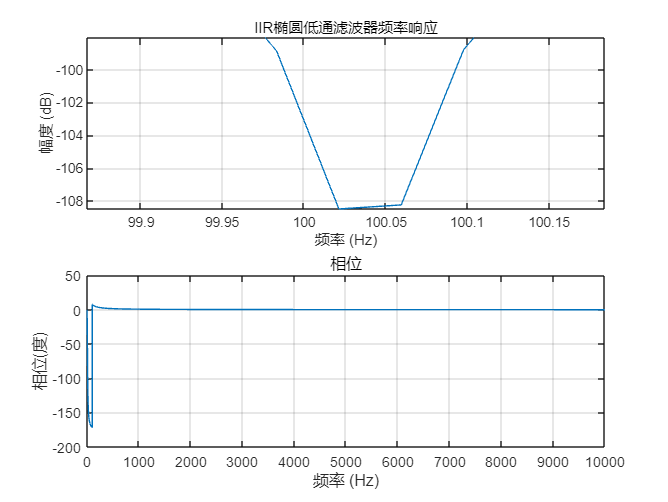


% 绘制频率响应
freqz(b, a, 65536*4, Fs);
title('IIR椭圆低通滤波器频率响应');
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
grid on;